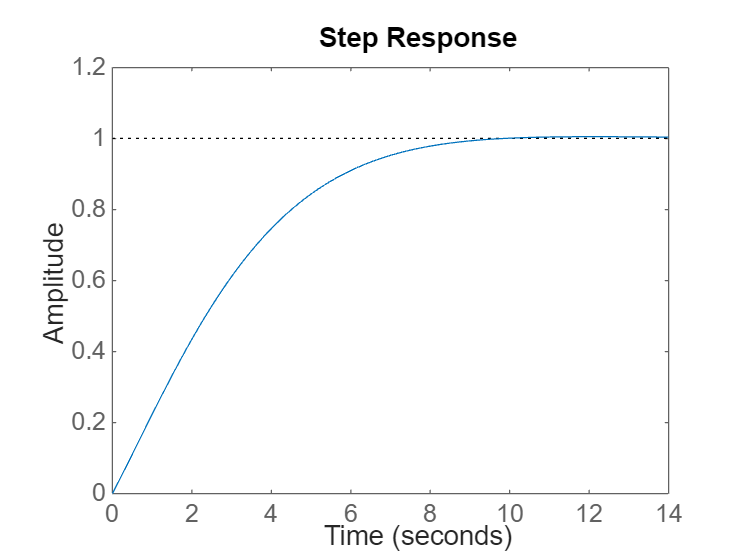

%%Reference tf
%km  = 1.6211e-04;
%bm  = 1;
%am1 = 0.0232;
%am2 = 1.6211e-04;
km  = 0.21261;
bm  = 1;
am1 = 0.8;
am2 = 0.2126;
%%Transfer fun
Tfm=tf([km km*bm],[1 am1 am2]);
%%Step
step(Tfm)

stepinfo(Tfm)  

ans = struct with fields:
         RiseTime: 5.3699
    TransientTime: 8.0796
     SettlingTime: 8.0796
      SettlingMin: 0.9027
      SettlingMax: 1.0051
        Overshoot: 0.5067
       Undershoot: 0
             Peak: 1.0051
         PeakTime: 12.0886


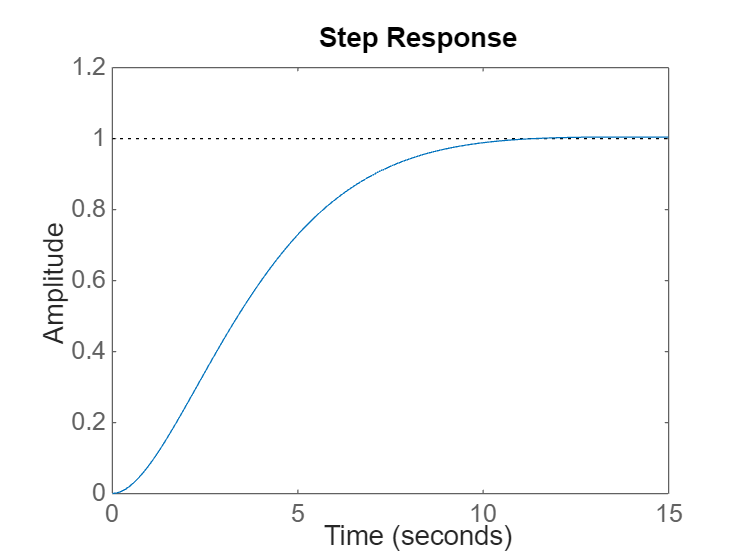

ans = struct with fields:
         RiseTime: 5.9441
    TransientTime: 9.4561
     SettlingTime: 9.4561
      SettlingMin: 0.9037
      SettlingMax: 1.0042
        Overshoot: 0.4175
       Undershoot: 0
             Peak: 1.0042
         PeakTime: 13.7004


% Definir el tiempo de asentamiento deseado
    Ts = 10; % segundos

    % Calcular los parámetros de la función de transferencia
    zeta = 0.8675; % coeficiente de amortiguamiento (ajustar según sea necesario)
    wn = 4 / (zeta * Ts); % frecuencia natural

    % Crear la función de transferencia
    sys = tf(wn^2, [1, 2*zeta*wn, wn^2]);
    step(sys); stepinfo(sys)

    ess_step = abs(1 - dcgain(sys))

ess_step = 0